Assignment1

- Image Manipulation 

a. The provided imageManip.m script reads in the provided u2dark.png photo and converts it to grayscale using rgb2gray. Use the script and your own code to calculate the following statistics: What is the average pixel value of the resulting grayscale image? What are the min and max values? (There are several ways to calculate these quantities in MATLAB. Review the MATLAB tutorial if you need help.)

Answer:

dark = (rgb2gray(imread('u2dark.png')));
avg1 = mean(dark(:))

avg1 = 76.9622

max1 = max(dark(:))

max1 = uint8
153

min1 = min(dark(:))

min1 = uint8
25

b. We would like to bring the image to a more typical average brightness. Add an offset and apply a scaling factor to all pixels, so that the minimum pixel value becomes 0 and the max pixel value becomes 255. (Cameras often do a similar function automatically.) Include the final image in your report, as well as the MATLAB code you used to produce it. 

Answer:

% specifying offset
offset = 255 - max1;

% adding brightness
brLevel = offset

brLevel = uint8
102

img_brightend = dark + brLevel;
figure(1); imshow(dark); title('gray image')
figure(2); imshow(img_brightend); title('brightend image')
% scaling image
l = 0;
u = 255;
imgMin = min(img_brightend(:))

imgMin = uint8
127

imgMax = max(img_brightend(:))

imgMax = uint8
255

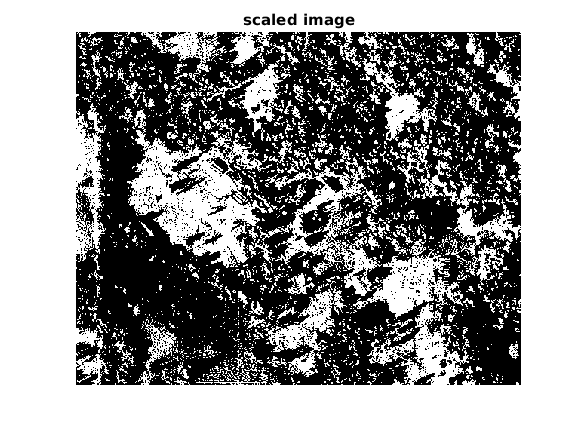

imgScaled = [(img_brightend - imgMin)./(imgMax - imgMin)].*(u-l);
figure(3); imshow(imgScaled) ; title('scaled image')

min_imgScaled = min(imgScaled(:))

min_imgScaled = uint8
0

max_imgScaled = max(imgScaled(:))

max_imgScaled = uint8
255

c. Next, we would like to double the contrast of the pixels in the middle brightness range. Specifically, take your result from part (b) and replace each pixel’s intensity i with a new intensity 𝑖′, where 𝑖′ = 2 ∗ (𝑖 − 128) + 128. Threshold 𝑖′ so that 0 ≤ 𝑖′ ≤ 255 (you can use the uint8 function). Include your MATLAB code and the resulting contrast-boosted image in your report. Compare the image to part (b). What was the downside of increasing contrast in this way, and why did it happen?

Answer:

[M N] = size(imgScaled)

M = 468

N = 591

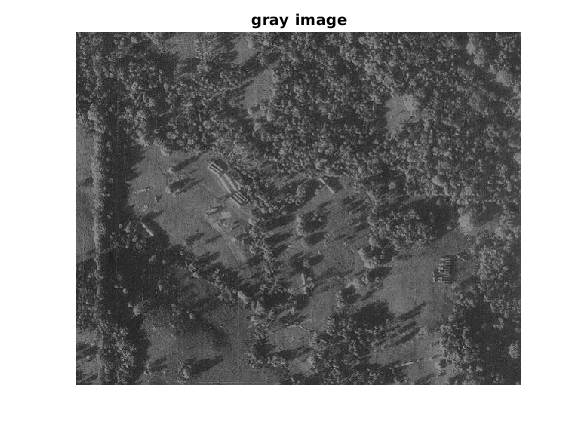

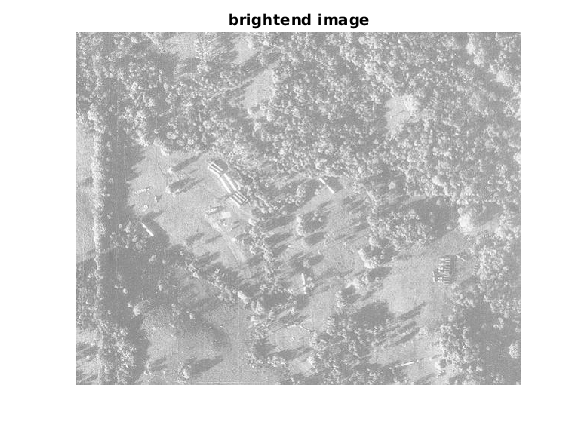

intensity = zeros([M N]);

for col=1:N
    for row=1:M
        var = uint8(imgScaled(row,col));
        if (0 <= 2*(var-128)+128) <= 255
            intensity(row,col) = (2*(var-128))+128;
            myvar = (2*(var-128))+128;
        else
            intensity(row,col) = double(imgScaled(row,col));
        end
    end
end

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
0

var = uint8
255

var = uint8
255

var = uint8
255

var = uint8
255

figure(4); imshow(uint8(intensity)); title('contrast-boosted image')
max2 = max(intensity(:))
min2 = min(intensity(:))

The contrast boosing filter is adding a white filter to the image. The white pixels' gray level is not changed and its been kept at 255 however the darkest part are now 128 instead of 0. It seems that the contrast between white and dark parts is decreased. 